clc; clear variables; close all
working_directory = 'C:\Users\haffnerf\WORKSPACE\inception-petroleum-analysis\';

% Load functions from the matlab directory
addpath(genpath(append(working_directory, 'matlab')));

% This script is fed by the full range dataset, % although it generates the reduced range dataset later 
% during the pre-processing stage.
data = append(working_directory, 'data\raw-kennard-full_range.mat');
load(data)

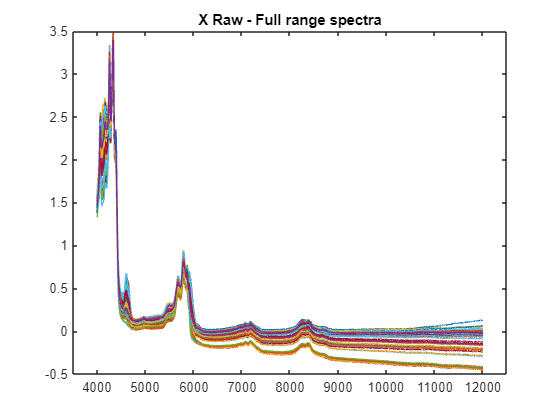

X = cat(1, X_train, X_test);
figure;
plot(W, X');
xlim([3500 12500]);
ylim([-.5 3.5]);
title(['X Raw - Full range spectra']);

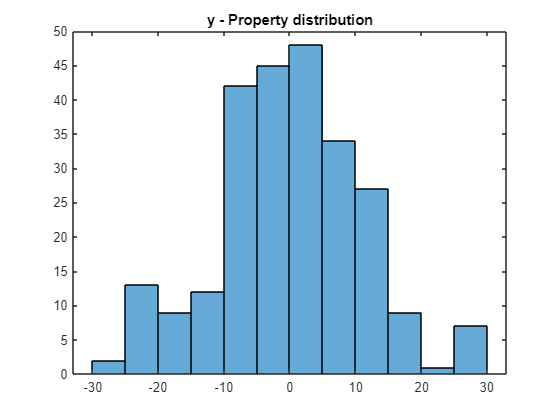

Y = cat(1, y_train, y_test);
figure;
histogram(Y');
title(['y - Property distribution']);

yMax = max(Y)

yMax = 29.8787

yMin = min(Y)

yMin = -25.1563

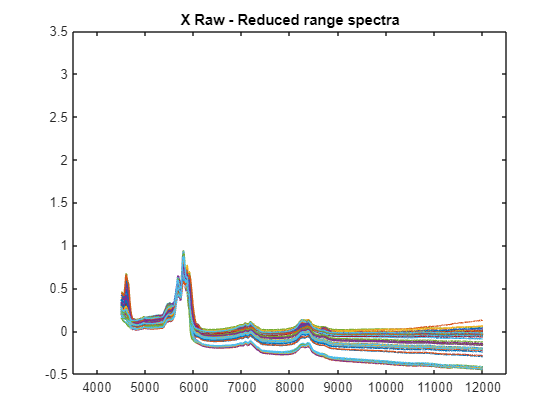

variable_selection=[4500 12000];
OPTCLB=0;
OPTCO=1;
[X_train_ws, axe]=fcorr(X_train,W(1,:),OPTCLB,variable_selection,OPTCO);
[X_test_ws, axe]=fcorr(X_test,W(1,:),OPTCLB,variable_selection,OPTCO);
figure; 
plot(axe, X_train_ws');
xlim([3500 12500]);
ylim([-.5 3.5]);
title(['X Raw - Reduced range spectra']);

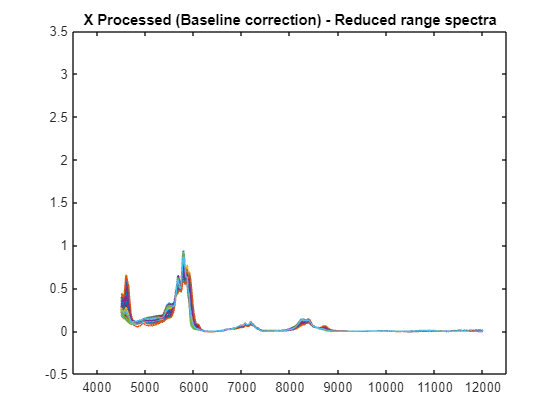

baseline_corr_order=2;
baseline_options=[];
[X_train_corr, allb, a] = wlsbaseline(X_train_ws, baseline_corr_order, baseline_options);
[X_test_corr, allb, a] = wlsbaseline(X_test_ws, baseline_corr_order, baseline_options);
figure;
plot(axe, X_train_corr');
xlim([3500 12500]);
ylim([-.5 3.5]);
title(['X Processed (Baseline correction) - Reduced range spectra']);

center_opt = 1;
X_train_corr = center(X_train_corr, center_opt);
X_test_corr = center(X_test_corr, center_opt);

nbfact = 6;
y_hat = pls_nipals_pred(X_train_corr, y_train, nbfact, 0, X_test_corr);
residual = y_test - y_hat;
rmsep = RMSEP(y_test, y_hat);
r2 = r_squared(y_test, y_hat);

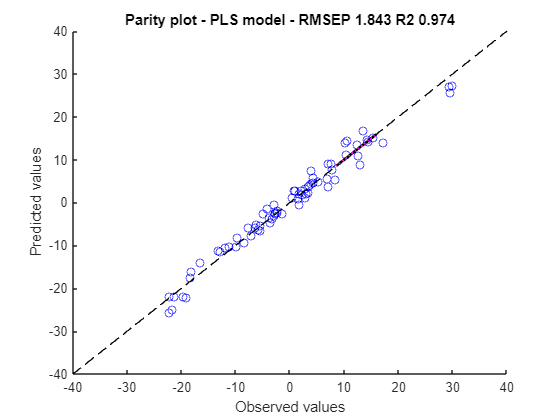

x_aux=[8.5,16]; R=[0.07,0.07];
ICR1=x_aux+(R./1.41) ; ICR2=x_aux-(R./1.41);

figure; hold on;
n_test = length(y_test);
for ical=1:n_test
    plot(y_test(ical),y_hat(ical),'ob');
end

line([-40 40],[-40 40], 'Color','black','LineStyle','--')
plot(x_aux, x_aux,'k','LineWidth',2);
plot(x_aux, ICR1,':m','LineWidth',1);
plot(x_aux, ICR2,':m','LineWidth',1);
xlabel('Observed values');
ylabel('Predicted values');
title(['Parity plot - PLS model - RMSEP ' num2str(round(rmsep,3)) ' R2 ' num2str(round(r2,3))]);

[tcal,pcal,btcal,bX,RMSEcal,SRcal,levcal,wgcal]=fwFPLS(X_train_corr, y_train, nbfact);

fitting_ratio = round((rmsep/RMSEcal),3)

fitting_ratio = 1.0050